## Hyperloop Thruster Calculations Simplified

### Rocket Equation


$$\Delta v = I_{sp} g_0 ln\frac{m_0}{m_f}$$



$$m_0 = m_f + \Delta m$$



$$\Delta m = V(\rho_1 - \rho_2)$$



$$m_f = m_{InertPod} + m_{Tank} + m_{ResidualProp}$$



$$m_{ResidualProp} = \rho_2V$$


### Isentropic Process


$$\frac{T_2}{T_1} = \left( \frac{P_2}{P_1} \right)^{ \frac{\gamma - 1}{\gamma}} = \left( \frac{\rho_2}{\rho_1} \right)^{\gamma - 1}$$


Thus for a temperature or pressure limited process,


$$\rho_2 = \rho_1 max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right]$$


### Combine Equations


$$\Delta v = I_{sp}g_0\ln\left( 1 +   \frac{ V \rho_1 \left( 1 - max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right] \right)   }{m_f}                 \right)$$


### Ideal Gas Law


$$\rho_1  = \frac{P_1(MM)}{RT_1}$$



$$\Delta v = I_{sp}g_0\ln\left( 1 +   \frac{ V \frac{P_1(MM)}{RT_1} \left( 1 - max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right] \right)   }{m_f}                 \right)$$



$$\Delta v = I_{sp}g_0\ln\left( 1 +   \frac{ V \frac{P_1(MM)}{RT_1} \left( 1 - max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right] \right)   }{m_{InertPod} + m_{Tank} + V \frac{P_1(MM)}{RT_1} max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right]}                 \right)$$


^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

In terms of rho:


$$\Delta v = I_{sp}g_0\ln\left( 1 +   \frac{ V (\rho_1 - \rho_2)  }{m_{InertPod} + m_{Tank} + V \rho_2}                 \right)$$


Alternatively solved for $m_{InertPod}$:


$$m_{InertPod} =  V \frac{P_1(MM)}{RT_1} \left( 1 - max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right] \right)   \left( e^{\frac{\Delta v}{I_{sp}g_0} } -1  \right)^{-1} - m_{tank} -  V \frac{P_1(MM)}{RT_1} \left( max\left[    \left(  \frac{T_2}{T_1} \right)^{\frac{1}{\gamma-1}}      ,    \left(  \frac{P_2}{P_1}  \right)^{\frac{1}{\gamma}}        \right] \right)$$


^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

In terms of rho:


$$m_{InertPod} =  \left( e^{\frac{\Delta v}{I_{sp}g_0}} -1 \right)^{-1}V(\rho_1-\rho_2)-m_{tank} - V\rho_2$$


%Constants
MM_N2 = 0.028; %kg/mol
g0 = 9.8; %[m/s]
R = 8.314; % J / (mol. · K)
ISP_air = 73; %sec
gamma_air = 1.4;

%Pod Specifications
m_pod_inert = lb_to_kg(322);%lb_to_kg(322);%kg pod inert mass (everything except the tanks and propellant)
disp(['The inert pod mass is ', num2str(m_pod_inert),' [kg]']);

The inert pod mass is 146.0566 [kg]


%Tank Specifications
P_tank_i = Psi_to_Pa(4800); %input in psi
T_tank_i = F_to_K(80); %Input F ambient temp

%2X10070504-2
%m_tank = 34.825; %kg
%Vol_tank = L_to_m3(200.8); %Input in L

%3X10070504-2 + 1X220074
m_tank = 67.45; %kg
Vol_tank = L_to_m3(343); %Input in L

rho_tank_i = P_tank_i*MM_N2 /(R*T_tank_i);
m_prop_loaded = rho_tank_i*Vol_tank;

T_tank_limit = F_to_K(-40); %Input in F
P_tank_limit = Psi_to_Pa(100); %input in psi (~ish, really a function of system hardware flow coefficient and mass flow rate...)

T_limit_rho_2 = (T_tank_limit/T_tank_i)^(1/(gamma_air-1));
P_limit_rho_2 = (P_tank_limit/P_tank_i)^(1/gamma_air);

if T_limit_rho_2>P_limit_rho_2
    disp('The system is temperature Limited')
else
    disp('The system is pressure Limited')
end

The system is temperature Limited


rho_tank_f = rho_tank_i*max(T_limit_rho_2,P_limit_rho_2);
P_tank_f = P_tank_i*(rho_tank_f/rho_tank_i)^gamma_air;
P_tank_f_psi = Pa_to_Psi(P_tank_f);
m_residual_prop = rho_tank_f*Vol_tank; %kg


Delta_v = m_s_to_km_hr(ISP_air*g0*log( 1 + ((Vol_tank*(rho_tank_i-rho_tank_f))/(m_pod_inert+m_tank+(rho_tank_f*Vol_tank))) ));
disp(['The Pod Delta V is: ', num2str(Delta_v), ' [km/hr]'])

The Pod Delta V is: 493.9295 [km/hr]


% for a given tank system, plot Delta v vs. InertPod mass
Inert_pod_linspace = linspace(lb_to_kg(0),lb_to_kg(500),500);

Delta_v_linspace = m_s_to_km_hr(ISP_air*g0*log( 1 + ((Vol_tank*(rho_tank_i-rho_tank_f))./(Inert_pod_linspace+m_tank+(rho_tank_f*Vol_tank))) ));

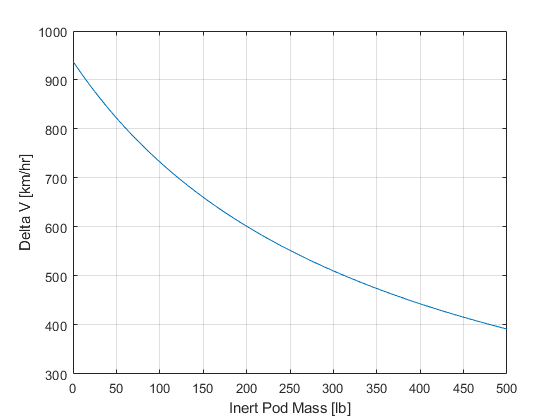

plot(kg_to_lb(Inert_pod_linspace),Delta_v_linspace);
grid on
xlabel('Inert Pod Mass [lb]')
ylabel('Delta V [km/hr]')

%title('Delta V v. Inert Pod Mass 3 X 10070504-2 + 1 X 220074 tank system')

## Mass flow Rate


$$\dot m = \frac{\Delta m }{t_{MECO}}$$


assume a constant mass flow rate and thus $m(t)$,


$$m(t) = m_0 - \dot m t$$



$$F = I_{sp}g_0 \frac{\Delta m}{t_{MECO}}$$



$$a(t) = \frac{F}{m(t)} = \frac{I_{sp}g_0 \Delta m}{t_{MECO}m(t)}$$



$$v(t) = \int  \frac{I_{sp}g_0 \Delta m}{t_{MECO}m(t)} dt$$


Solve, and set $v(0) = 0$,


$$v(t) = -I_{sp}g_0 \ln \left[ m(t)   \right] + I_{sp}g_0ln(m_0)$$



$$x(t) = \int v(t) dt$$


Solve (U substitution) and set $x(0) = 0$


$$x(t) = I_{sp}g_0\frac{t_{MECO}}{\Delta m} \left[  m(t) \ln[m(t)] - m(t)  \right] + I_{sp}g_0\ln(m_0)t - \frac{I_{sp}g_0t_{MECO}}{\Delta m} \left[ m_0 \ln(m_0) - m_0   \right]$$


set


$$x(t_{MECO}) = x_{ThrustLen}$$



$$t_{MECO} = x_{ThrustLen} \left[  I_{sp}g_0 \left(  \frac{1}{\Delta m} (m_f \ln(m_f) - (m_f - \Delta m) \ln(m_f - \Delta m) - \Delta m) + \ln(m_f - \Delta m)   \right)   \right]^{-1}$$


m_f = m_pod_inert+m_tank+(rho_tank_f*Vol_tank);
m_0 = m_pod_inert+m_tank+(rho_tank_i*Vol_tank);
Delta_m = m_0-m_f;

x_Thrust_len = 600; %m

t_MECO = x_Thrust_len*(ISP_air*g0*((1/Delta_m)*(m_f*log(m_f) - m_0*log(m_0) + Delta_m)  +log(m_0)  ))^(-1);
disp(['t MECO: ', num2str(t_MECO), ' [sec]'])

t MECO: 9.0348 [sec]


m_dot = Delta_m/t_MECO;
disp(['Average Mass Flow Rate: ', num2str(m_dot), ' [kg/sec]'])

Average Mass Flow Rate: 6.5871 [kg/sec]


Thrust = ISP_air*m_dot*g0;
disp(['Average Thrust: ', num2str(Thrust), '[N]'])

Average Thrust: 4712.387[N]


%max acceleration
a_max = (Thrust/m_f)*(1/g0); %in terms of g
disp(['Max Acceleration: ', num2str(a_max), '[g]']);

Max Acceleration: 1.7082[g]


%simple model check
t_min = sqrt(2*m_f*x_Thrust_len/(ISP_air*m_dot*g0));
t_max = sqrt(2*m_0*x_Thrust_len/(ISP_air*m_dot*g0));

t_linspace = linspace(0,t_MECO,500);
m_of_t = m_0 - m_dot*t_linspace;
v_lin = ISP_air*g0*log(m_0./(m_0 - m_dot*t_linspace));
x_lin =  t_MECO*ISP_air*g0*((1/Delta_m)*(m_of_t.*log(m_of_t) - m_0*log(m_0) + m_dot.*t_linspace)  + (t_linspace./t_MECO)*log(m_0) );

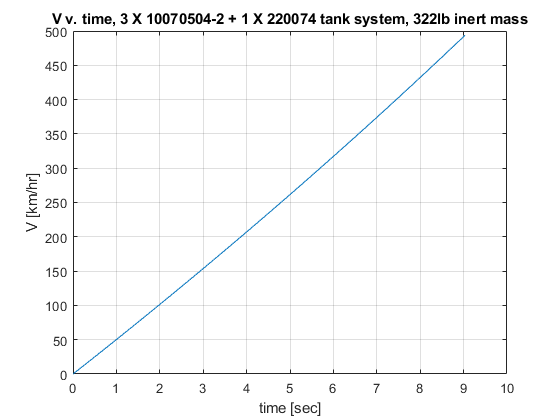

plot(t_linspace,m_s_to_km_hr(v_lin));
grid on
xlabel('time [sec]')
ylabel('V [km/hr]')
title('V v. time, 3 X 10070504-2 + 1 X 220074 tank system, 322lb inert mass')

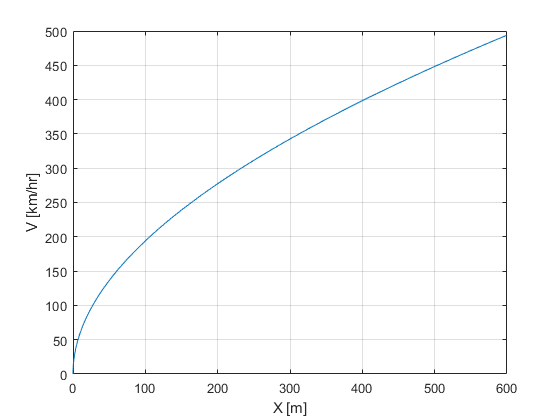

plot(x_lin,m_s_to_km_hr(v_lin));
grid on
xlabel('X [m]')
ylabel('V [km/hr]')

%title('Velocity v. X, 3 X 10070504-2 + 1 X 220074 tank system, 322lb inert mass')


$$\dot m_{M1} = A_t p_1 k \frac{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}{\sqrt{kRT_1}}$$


R is the specific gas constant. Solve for $A_t$ given tank inlet pressure to find minimum oriface.


$$d_{O-min} = 2\left( \frac{1}{\pi}\frac{\dot m}{p_1k} \frac{\sqrt{kRT_1}}{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}} \right)^\frac{1}{2}$$


At a minimum when $T_1$ is smallest and $p_1$ greatest. These don't occur simultaneously 

%avoid supersonic flow at the minimum oriface withing valve/regulator
%hardware
R_spec = R/MM_N2;
k_N2 = 1.4;
Orifice_min = m_to_in(2*( (m_dot/(pi*P_tank_i*k_N2))  *sqrt((k_N2*R_spec*T_tank_i)/( (2/(k_N2+1))^((k_N2+1)/(k_N2-1))   )))^(1/2));
%this number is the absolute maximum possible, will actually be some
%combination of p1 and t1
disp(['The system must have a minium oriface greater than: ', num2str(Orifice_min), ' [in] diameter']);

The system must have a minium oriface greater than: 0.41372 [in] diameter



$$d_{O-min} = 0.304 [in]$$


What is the necessary pressure gradient, given the flow coefficients of the hardware to provide a sufficient mass flow rate?

Flow Coefficient in metric:


$$K_v = Q \sqrt \frac{SG}{\Delta P}$$


Metric Flow Coefficient: $K_v [m^3hr^{-1}bar^{-0.5}]$

Flow Rate: $Q [m^3hr^{-1}]$

SG: Specific gravity, $\rho_{water} = 1$

Pressure Gradient: $\Delta p [bar]$


$$\dot m = Q \rho$$



$$\dot m = K_v \sqrt{ \Delta p \rho_{water} \rho}$$


MIND THE UNIT CONVERSTIONS

Flow coefficients in series add like:


$$\frac{1}{(K_{vt})^2} =  \frac{1}{(K_{v1})^2} + \frac{1}{ (K_{v2})^2}$$
   

Solve for $\Delta p$ to determine inlet pressure...


$$\Delta p = \left( \frac{ \dot m}{K_{vt}} \right) ^2 \frac{1}{\rho \rho_{water}}$$


The regulator will keep the nozzle inlet pressure constant, thus the pressure gradient is a minimum when the tank pressure is also at a minimum, $p_f$. Also when $\rho$ is a minimum


$$p_{NozzleInlet} < p_f - \left( \frac{ \dot m}{K_{vt}} \right) ^2 \frac{1}{\rho \rho_{water}}$$


%Flow-Tek HP Model Ball valve C_v ~ 7.5 1/2"
%EMERSON 44-4200 Regulator 1/2" C_v ~ 3.3
%EMERSON 44-4200 Regulator 5/8" C_v ~ 6 2X system....
%EMERSON 44-4200 Regulator 1" C_v ~ 12 HP
Primary_valve_K_v = C_v_to_K_v(32);
Reg_K_v = C_v_to_K_v(12);

K_v_tot = (2*((1/Primary_valve_K_v)^2)+(1/(Reg_K_v^2)))^(-1/2);

Convert $K_v$ from $[m^3hr^{-1}bar^{-0.5}]$ to $[m^3sec^{-1}Pa^{-0.5}]$


$$\frac{m^3}{hr \sqrt{bar}} = \frac{1}{60^2 \sqrt{10^5}} \frac{m^3}{sec \sqrt{Pa}}$$


k_v_m3_sec_Pa = (1/(60^2))*(1/sqrt(10^5))*K_v_tot;

rho_water = 997; %kg/m3
p_inlet_max = P_tank_f - ((m_dot/k_v_m3_sec_Pa)^2)*(1/(rho_tank_f*rho_water));
p_inlet_max_psi = Pa_to_Psi(p_inlet_max);

%for 3X10070504-2 + 1X220074 need smaller throat so define larger p1, need
%lower mass flow rate.... or upgrade pressure reg. again....

## Nozzle Geometry

Throat Diameter


$$A_t = \frac{\dot m}{p_1 k} \frac{\sqrt{kRT_1}}{\sqrt{ \left[ \frac{2}{k+1} \right]^{(k+1)/(k-1)}}}$$


$T_1$ will vary, use minimum value. Find minimum $A_t$ requirement.

p_inlet = p_inlet_max;
%p_inlet = Psi_to_Pa(1200);


p_inlet_psi = Pa_to_Psi(p_inlet);
A_t = (m_dot/(p_inlet*k_N2)) * sqrt(k_N2*R_spec*T_tank_limit) * (1/(sqrt(  (2/(k_N2+1))^((k_N2+1)/(k_N2-1))  ))); %m2
d_t = 2*sqrt(A_t/pi); %m
d_t_in = m_to_in(d_t);%in if > pipe d it's already supersonic.... need higher inlet pressure.... or lower mass flow rate... via increasing thrust length

Expansion Ratio


$$\epsilon = \frac{A_2}{A_t} = \left(  \frac{k+1}{2} \right)^{\frac{1}{k-1}} \left( \frac{p_2}{p_1} \right)^{\frac{1}{k}} \sqrt{ \frac{k+1}{k-1} \left[  1 - \left(   \frac{p_2}{p_1} \right)^{\frac{k-1}{k}}   \right]   }$$



$$A_t \epsilon = A_2$$



$$d_t \sqrt{\epsilon} = d_2$$


p_2 = 0.125;%pressure in tube [psi]
p_2_1atm = 14.7;%ambient 1 atm [psi]


exp_ratio_vac = exp_ratio(k_N2,p_2,p_inlet_psi);

e = 219.4356

exp_ratio_1atm = exp_ratio(k_N2,p_2_1atm,p_inlet_psi);

e = 8.2128

d_2 = d_t * sqrt(exp_ratio_vac);
d_2_in = m_to_in(d_2); 

disp(['The vaccum exit diameter ', num2str(d_2_in), '[in]']) %if this is too large, consider multipul nozzles...

The vaccum exit diameter 10.3073[in]



d_2_1atm = d_t * sqrt(exp_ratio_1atm);
d_2_1atm_in = m_to_in(d_2_1atm); 

disp(['The 1atm exit diameter ', num2str(d_2_1atm_in), '[in]'])

The 1atm exit diameter 1.9941[in]


## Test an unregulated case

optimize for minimum tank pressure, thus always underexpanded. Fix nozzle geometry

C_f_test = Coefficient_of_Thrust_Optimal(k_N2,0.125,P_tank_f_psi)

C_f_test = 1.7536

A_t_test = (m_dot/(P_tank_f*k_N2)) * sqrt(k_N2*R_spec*T_tank_limit) * (1/(sqrt(  (2/(k_N2+1))^((k_N2+1)/(k_N2-1))  ))); %m2
F = C_f_test*A_t_test*P_tank_f

F = 4.4387e+03

function K = F_to_K(temp_F)
    K = (temp_F-32)*(5/9)+273.15;
end

function Psi = Pa_to_Psi(press)
    Psi = press/6894.76;
end

function Pa = Psi_to_Pa(press)
    Pa = press*6894.76;
end

function m_kg = lb_to_kg(m_lb)
    m_kg = 0.453592*m_lb;
end

function m_lb = kg_to_lb(m_kg)
    m_lb = m_kg/0.453592;
end

function K_v = C_v_to_K_v(C_v) %GPM psi to m3/hr bar
    K_v = C_v * 0.862;
end

function v = km_hr_to_m_s(s)
    v = s * 0.277778;
end

function v = m_s_to_km_hr(s)
    v = s / 0.277778;
end

function vol_m3 = L_to_m3(vol_L)
    vol_m3 = vol_L*0.001;
end

function l = in_to_m(len)
    l = len*0.0254;
end

function l = m_to_in(len)
    l = len/0.0254;
end

function kv = c_v_to_k_v_sec(Cv)
    kv = 0.865*Cv*(1/3600);
end

function x_b = braking_dist(v,m,mu,N)
    x_b = (v^2)*(1/2)*(m/(N*mu));
end

function e = exp_ratio(k,p2,p1) %expansion ratio
    e = 1 / ( (((k+1)/(2))^(1/(k-1))) * ((p2/p1)^(1/k)) * (( (k+1)/(k-1) ) * (1 - ((p2/p1)^((k-1)/k))) )^(1/2))
end

function C_f = Coefficient_of_Thrust_Optimal(k,p2,p1)
    C_f = ( ((2*k^2)/(k-1)) * ((2/(k+1))^((k+1)/(k-1))) * (1 - (p2/p1)^((k-1)/k))  )^(1/2);
end